Discussion HW2

A spherical object, e.g. a baseball, is moving in air with an initial speed of 30 m/s and an initial angle of 30 degrees above the horizon. Use a mass m = 0.15 kg, diameter D = 7 cm, and γ = 0.25 N/s`2`m`4`, g = 10 m/s`2`

**1.** Derive and write down the differential equations for the speeds vx(t) and vz (t).


$$\begin{array}{l}
F_{\textrm{Drag}} =-\textrm{cv}\vec{v} =m\frac{d\vec{v} }{\textrm{dt}}\\
\frac{dv_x }{\textrm{dt}}=-\frac{c}{m}v_x \vec{v} 
\end{array}$$



$$\begin{array}{l}
\frac{dv_z }{\textrm{dt}}=-g-\frac{c}{m}v_z \vec{v} \\
\vec{v} =\sqrt{v_x^2 +v_z^2 }
\end{array}$$


**2.** Write down the finite difference versions for the differential equations. Add a sentence saying how you would implement the equations if you were to use a worksheet. (Feel free to use a worksheet, but this is not required, and don’t submit it. You can use the worksheet to check your solutions for later sections.)


$$\begin{array}{l}
\frac{v_x \left(t+\Delta t\right)-v_x \left(t\right)}{\Delta t}=-\frac{c}{m}v_x \left(t\right)\vec{v\left(t\right)} \\
v_x \left(t+\Delta t\right)=v_x \left(t\right)-\Delta t\frac{c}{m}v_x \left(t\right)\vec{v\left(t\right)} 
\end{array}$$



$$\begin{array}{l}
\frac{v_z \left(\Delta t+t\right)-v_z \left(t\right)}{\Delta t}=-g-\frac{c}{m}v_z \left(t\right)\vec{v\left(t\right)} \\
v_z \left(\Delta t+t\right)=v_z \left(t\right)-\Delta t\left(g+\frac{c}{m}v_z \left(t\right)\vec{v\left(t\right)} \right)
\end{array}$$


To use these equations you would have to start with an initial velocity and time step as well as an angle or a initial velocity component so you can find the initial velocities of both components. Then you would have to fill out the at the same time to have the right numbers to calculate the next step.

**3.** Write a MATLAB livescript to solve the speeds vx(t) and vz (t). Use enough time to make the physics clear. The new element here, compared to what has been done in the discussion (and should be posted soon), is that we are solving for two speeds, not one. So the function we use in ODE45 needs to calculate and output two values not one. Consult the additional help below with this issue.

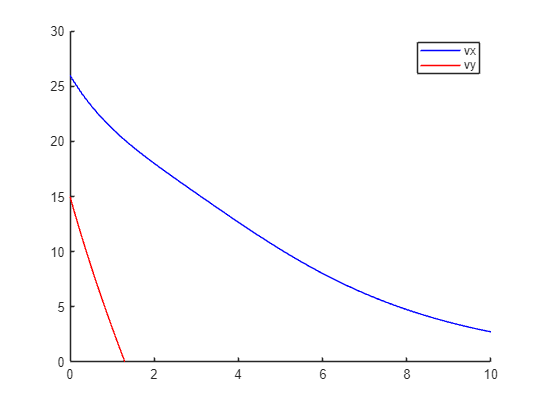

clc; clear all; close all;
v0 = 30;
theta = 30;
function dvdt = odefun(t, v)
% variables
gamma = 0.25;
D = 0.07;
c = gamma*D^2;
m = 0.15;
g = 10;
% initialize empty array
dvdt = zeros(2, 1);
% set x as first element
dvdt(1) = -(c/m)*v(1)*sqrt(v(1)^2+v(2)^2);
% set z as second element
dvdt(2) = -g -(c/m)*v(2)*sqrt(v(1)^2+v(2)^2);
end
[t, v] = ode45(@odefun, linspace(0, 10, 100), [v0*cosd(theta), v0*sind(theta)]);
hold on
plot(t, v(:, 1), 'Color', 'blue')
plot(t, v(:, 2), 'Color', 'red')
ylim([0, 30])
hold off
legend('vx', 'vz')